## 制御システム

次の状態方程式で表される線形システムを考える．


$$\dot{x}(t)=Ax(t)+Bu(t)$$



$$y(t)=Cx(t)+Du(t)$$


ここで，xが状態ベクトル，uが入力，yが出力である．

A=[0,1,0; 0,-0.01,0.02; 0,-2,-10];
B=[0;0;1];
C=[2 1 0];
D=0;
% 可制御性の確認
Co = ctrb(A,B);
rank(Co)

ans = 3

## 最適レギュレータ

最適レギュレータでは，次式で表される評価関数Jを最小化するような入力 u(t) を求める.


$$J=\int_o^\infty (x^TQx+u^TRu)dt$$


*Q*と*R*は重み行列であり，*x*を重視するか*u*を重視するかを決める. 

Q=[1 0 0;0 1 0;0 0 1];
R=0.2;

閉ループシステムの安定が達成されるフィドバックゲインKはリカッチ方程式


$$PBR^{-1}B^TP-PA-A^TP-Q=0$$


の解となる．


$$K=R^{-1}B^TPx$$


% リカッチ方程式の解
[K, P]=lqr(A,B,Q,R)

K =     2.2361   41.4861    0.3276


P = 	1.0e+03 *

    0.0218    0.2309    0.0004
    0.2309    4.2729    0.0083
    0.0004    0.0083    0.0001


評価関数Jを最小にする入力は以下のようになる．


$$u(t)=-R^{-1}B^TPx=-Kx(t)$$


## レギュレータなしの初期応答

% 初期値
x0=[3,10,2];

% 最適レギュレータなしの応答
sys = ss(A,B,C,D);
[y,t,x]=initial(sys,x0);

%プロット
clf
figure(1),grid,hold

現在のプロットをホールドしました


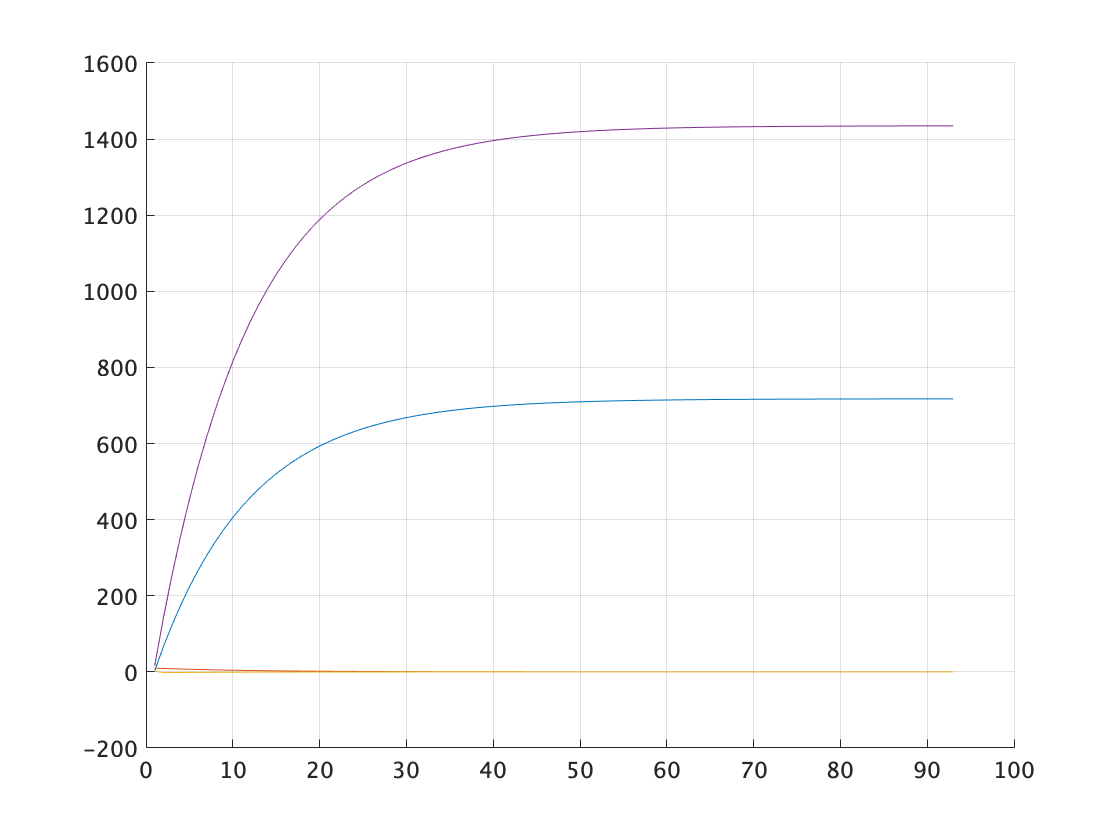

plot(x);
plot(y);

## 最適レギュレータを適応した初期応答

% 最適レギュレータを適応した初期応答
sys = ss(A-B*K,B*0,C,D);
[y,t,x]=initial(sys,x0);

%プロット
clf
figure(1),grid,hold

現在のプロットをホールドしました


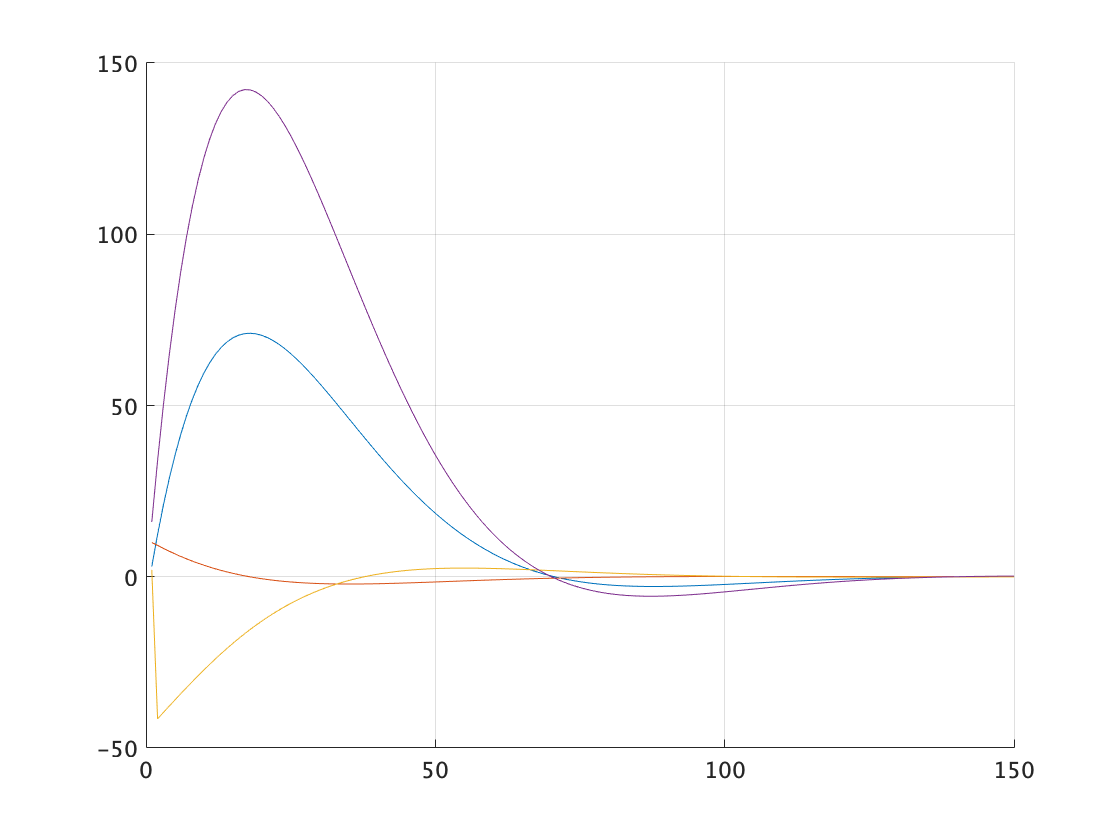

plot(x);
plot(y);